# Quiz Chap_symters 8 through 8.3

# Rigid-Body Motions

#### Q1 - Calculate $I_b$

- Consider an iron dumbbell consisting of a cylinder connecting two solid ss at either end of the cylinder.  The  density of the dumbbell is 5600 kg/m33.  

- The cylinder has a diameter of 4 cm and a length of 20 cm.  Each sphere has a diameter of 20 cm. Find the ap_symp_symroximate rotational inertia matrix 𝐼𝑏I*b*� in a frame {b} at the center of mass with z-axis aligned with the length of the dumbbell. 

- Your entries should be written in units of kg-m^2, and the maximum allowable error for any matrix entry is 0.01, so give enough decimal p_symlaces where necessary.

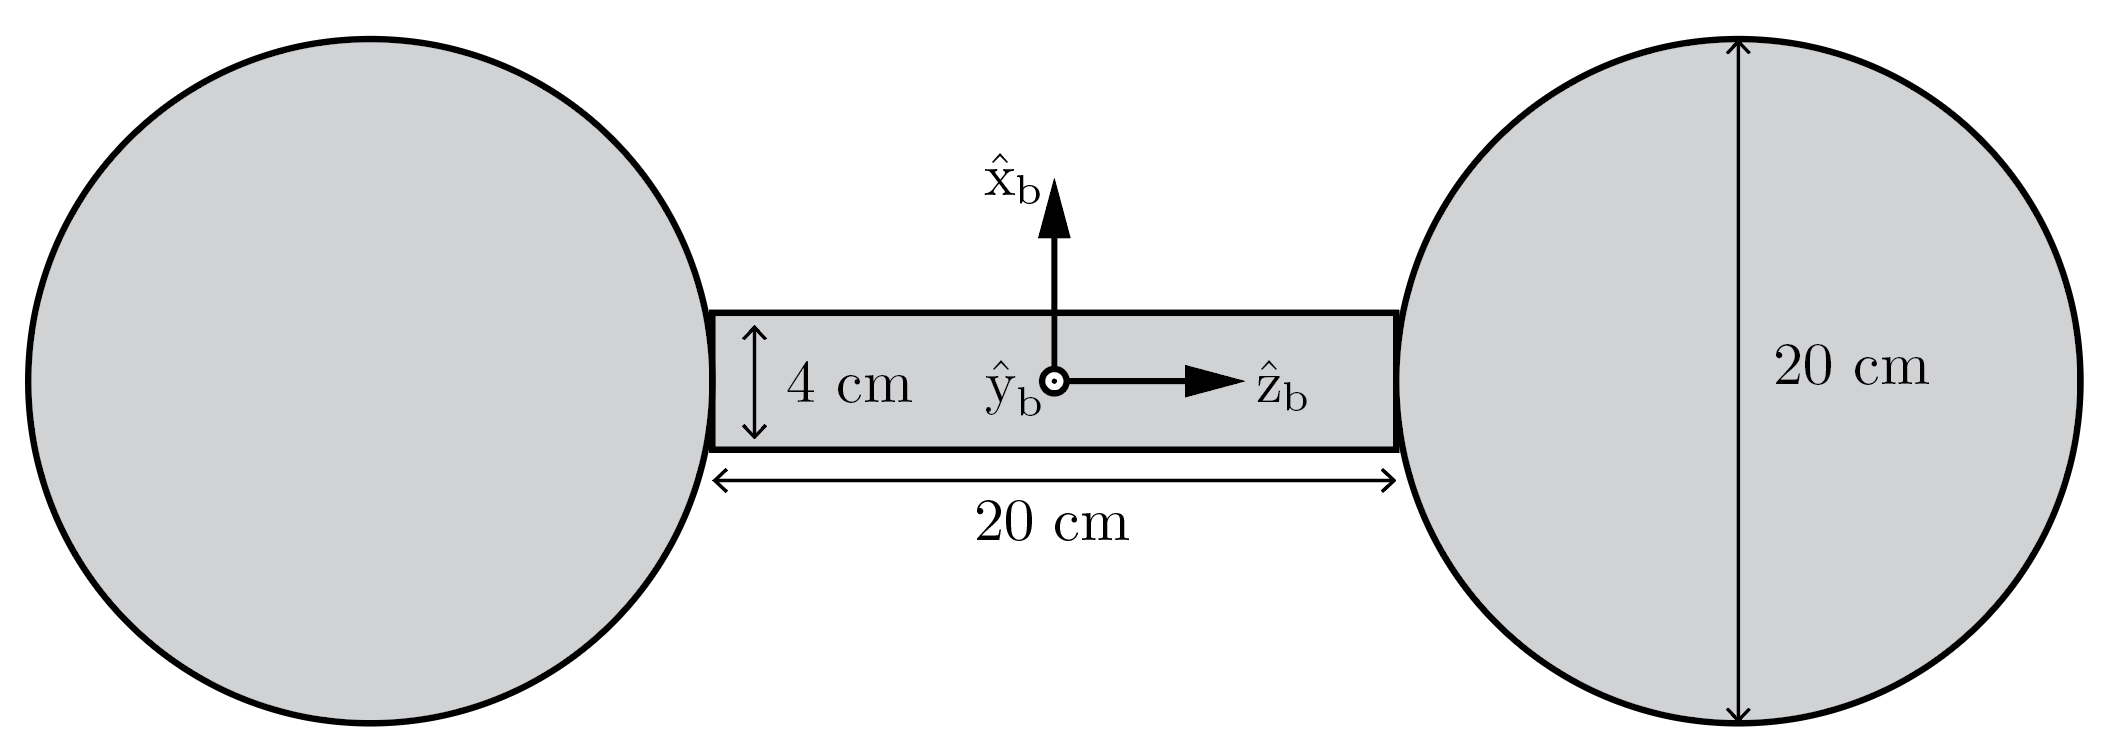

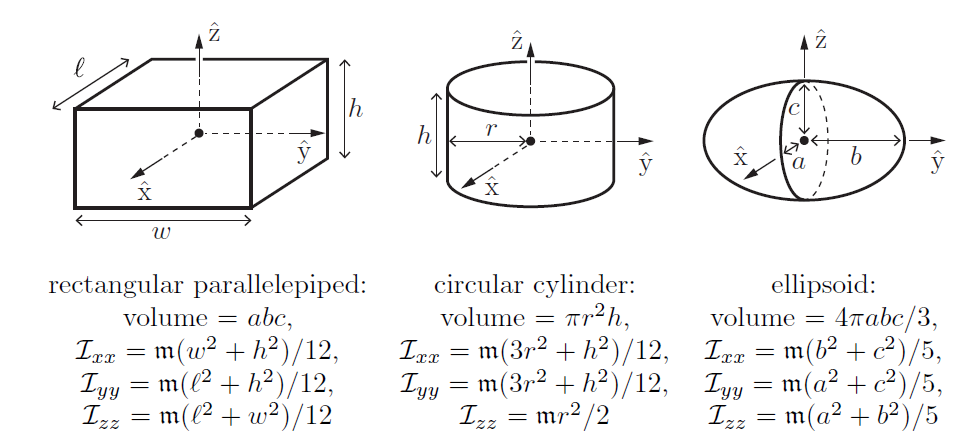


$$\rho =5600\mathrm{kg}/m^3$$
  

Esfera -> radio = 10cm = 0.1m

masa = p_sym * V

p = 5600;

r_c = 0.02;
h_c = 0.2;
V_c = pi*(r_c^2)*h_c;
m_c = p*V_c;
Ixx = (m_c*((3*r_c^2)+h_c^2))/12;
Iyy = Ixx;
Izz = (m_c*r_c^2)/2;

Ic = [   Ixx,  0,  0;
            0,  Iyy,0;
            0,  0,  Izz];
r_s = 0.1;
d = 0.2;    %distance between cm of sphere and point b
V_s = ((4/3)*pi*(r_s^3));
m_s = p*V_s;
I_s = (m_s*(r_s^2+r_s^2))/5;

I_sb = I_s + m_s*d^2;

Is1 = [   I_sb,  0,  0;
            0,  I_sb,0;
            0,  0,  I_s];

I_dumbell =     2.0691         0         0
         0    2.0691         0
         0         0    0.1879


Is2 = Is1;
I_dumbell = Is1 + Is2 + Ic

#### Q5 - UR5

addpath('C:\Users\Lenovo\Documents\MATLAB\Modern Robotics\mr')

M01 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.089159; 0, 0, 0, 1];
M12 = [0, 0, 1, 0.28; 0, 1, 0, 0.13585; -1, 0, 0, 0; 0, 0, 0, 1];
M23 = [1, 0, 0, 0; 0, 1, 0, -0.1197; 0, 0, 1, 0.395; 0, 0, 0, 1];
M34 = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.14225; 0, 0, 0, 1];
M45 = [1, 0, 0, 0; 0, 1, 0, 0.093; 0, 0, 1, 0; 0, 0, 0, 1];
M56 = [1, 0, 0, 0; 0, 1, 0, 0; 0, 0, 1, 0.09465; 0, 0, 0, 1];
M67 = [1, 0, 0, 0; 0, 0, 1, 0.0823; 0, -1, 0, 0; 0, 0, 0, 1];
G1 = diag([0.010267495893, 0.010267495893,  0.00666, 3.7, 3.7, 3.7]);
G2 = diag([0.22689067591, 0.22689067591, 0.0151074, 8.393, 8.393, 8.393]);
G3 = diag([0.049443313556, 0.049443313556, 0.004095, 2.275, 2.275, 2.275]);
G4 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
G5 = diag([0.111172755531, 0.111172755531, 0.21942, 1.219, 1.219, 1.219]);
G6 = diag([0.0171364731454, 0.0171364731454, 0.033822, 0.1879, 0.1879, 0.1879]);
Glist = cat(3, G1, G2, G3, G4, G5, G6);
Mlist = cat(3, M01, M12, M23, M34, M45, M56, M67); 
Slist = [0,         0,         0,         0,        0,        0;
         0,         1,         1,         1,        0,        1;
         1,         0,         0,         0,       -1,        0;
         0, -0.089159, -0.089159, -0.089159, -0.10915, 0.005491;
         0,         0,         0,         0,  0.81725,        0;
         0,         0,     0.425,   0.81725,        0,  0.81725];

thetalist = [0; pi/6; pi/4; pi/3; pi/2; 2*pi/3];
dthetalist = [0.2; 0.2; 0.2; 0.2; 0.2; 0.2];
ddthetalist = [0.1; 0.1; 0.1; 0.1; 0.1; 0.1];
g = [0; 0; -9.81];
Ftip = [0.1; 0.1; 0.1; 0.1; 0.1; 0.1];

taulist =     0.0128
  -41.1477
   -3.7809
    0.0323
    0.0370
    0.1034



taulist = InverseDynamics(thetalist,dthetalist,ddthetalist, g,Ftip,Mlist,Glist,Slist)